# Kane-Mele Model / Zeeman Berry Curvature

This note is used to calculate **spin hall effect**


$$H=\sum_{\langle ij\rangle \alpha}tc_{i\alpha}^\dag c_{j\alpha}+\sum_{\langle\langle ij\rangle\rangle \alpha\beta}i\lambda_{so} (\hat{d}_{ik}\times\hat{d}_{kj})s^z_{\alpha\beta}c^\dag_{i\alpha}c_{j\beta}+i\lambda_R\sum_{<ij>}c_i^\dag(s\times d)c_j+\lambda_v\sum_i\epsilon_i c_i^\dag c_i$$


where the first term and third term are both nearest neighbour hoppping, but the later represents the Rashba spin-orbit coupling (SOC) that **breaks the Time Reversal Symmetry **$\mathcal{T}$, the second term is intrinsic SOC (preserved the time reversal symmetry $\mathcal{T}$) and the last term is on-site energy with $\epsilon_i =\pm 1$ for A/B sublattice.

function syst = Kane_mele_Model(options)
% KANE_MELE_MODEL construct the syst by using the packet TB_Hamilton
% 
% Parameters
% ------
% t : nearest neighbour hopping (default 1).
% lam_so : intrinsic SOC that is the next nearest neighbour.
% lam_v : stagger sublattice potential.
% lam_R : Rashba SOC that is the nearest neighbour hopping.
% Translation : translation vector default [1,0;0,1] that is the case of
% bulk, you can set Translation = [] for site-site space or [1,0]/[0,1] for
% the ribbon case.
% Ns : The size of site.
%
% Return
% ------
% syst : A struct of TB_Hamilton.Builder
arguments
    options.t = 1;
    options.lam_so (1,1);
    options.lam_v  (1,1);
    options.lam_R  (1,1);
    options.Translation = [1,0;0,1];
    options.Ns = 5;
end
t = options.t; lam_so = options.lam_so; lam_R=options.lam_R; lam_v = options.lam_v;
Ns = options.Ns;
sx = [0,1;1,0]; sy = [0,-1i;1i,0];  sz = [1,0;0,-1];
vec = [-sqrt(3)/2 , 3/2; sqrt(3)/2,3/2];
basis = [0,0;0,1];
name = ["A","B"];
lat = TB_Hamilton.general(vec,name,basis,[2,2]);


lat.shape = polyshape(Ns*[0,-2*sqrt(3),0,2*sqrt(3),0],Ns*[0,6,12,6,0]-ones(1,5)*.5);
syst = TB_Hamilton.Builder(lat,options.Translation);
lats = lat.sublattice;

% on-site
syst(TB_Hamilton.Builder.HoppingKind(lats{1},lats{1},[0,0])) = lam_v*eye(2);
syst(TB_Hamilton.Builder.HoppingKind(lats{2},lats{2},[0,0])) = -lam_v*eye(2);

% nearest hopping
d = lats{2}.pos([0,0]) - lats{1}.pos([0,0]);
syst(TB_Hamilton.Builder.HoppingKind(lats{1},lats{2},[0,0])) = t*eye(2) + 1i*lam_R*(sx*d(2)-sy*d(1));

d = lats{1}.pos([0,1]) - lats{2}.pos([0,0]);
syst(TB_Hamilton.Builder.HoppingKind(lats{2},lats{1},[0,1])) = t*eye(2) + 1i*lam_R*(sx*d(2)-sy*d(1));

d = lats{1}.pos([1,0]) - lats{2}.pos([0,0]);
syst(TB_Hamilton.Builder.HoppingKind(lats{2},lats{1},[1,0])) = t*eye(2) + 1i*lam_R*(sx*d(2)-sy*d(1));


% next nearest hopping
syst(TB_Hamilton.Builder.HoppingKind(lats{1},lats{1},[1,0])) = -1i*lam_so*sz;  
syst(TB_Hamilton.Builder.HoppingKind(lats{1},lats{1},[0,1])) = 1i*lam_so*sz;
syst(TB_Hamilton.Builder.HoppingKind(lats{1},lats{1},[-1,1])) = -1i*lam_so*sz;

syst(TB_Hamilton.Builder.HoppingKind(lats{2},lats{2},[1,0])) = 1i*lam_so*sz;
syst(TB_Hamilton.Builder.HoppingKind(lats{2},lats{2},[0,1])) = -1i*lam_so*sz;
syst(TB_Hamilton.Builder.HoppingKind(lats{2},lats{2},[-1,1])) = 1i*lam_so*sz;
syst.finalized;
end


clc;clear;
syst = Kane_mele_Model(lam_so = .1,lam_v = .1,lam_R = 0.05,Translation=[],Ns=2);
figure
TB_Hamilton.Plot.ScatterRegion(syst);
axis off
figure
TB_Hamilton.Plot.FBZ(syst)

## Band Energy

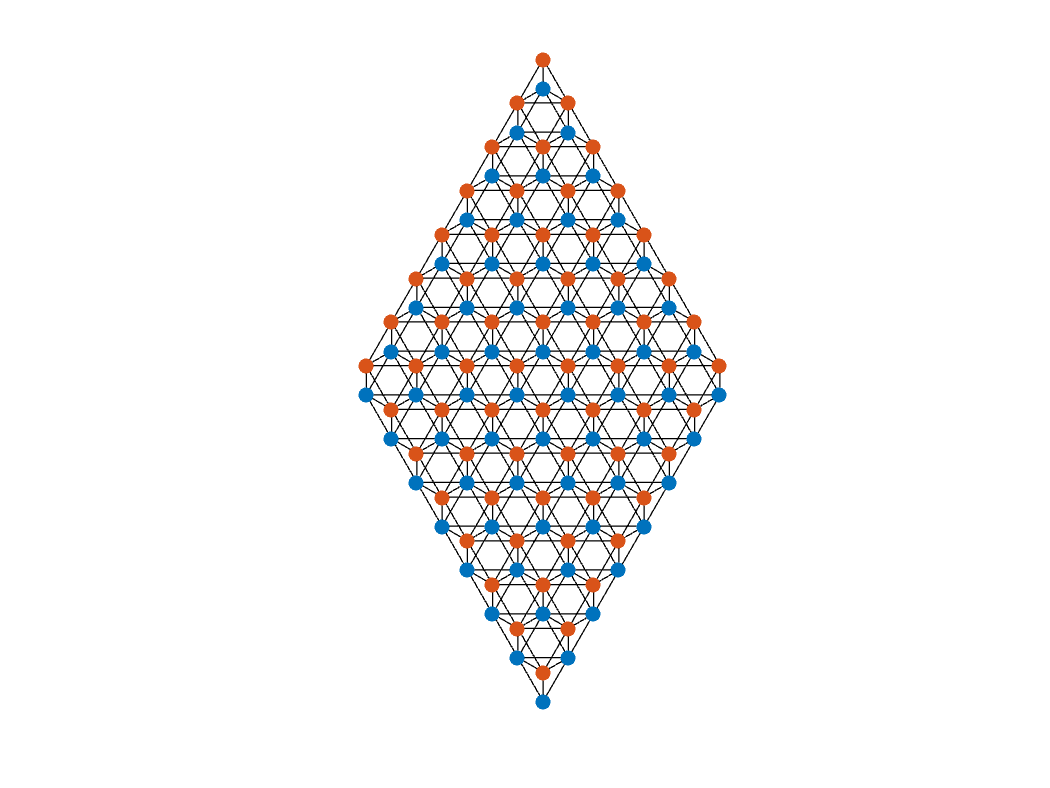

%%% Build the syst
% syst = Kane_mele_Model(lam_so = -.06,lam_v = .7,lam_R = 0.05);
syst = Kane_mele_Model(lam_so = -.24,lam_v = .7,lam_R = 0.05);
kx = linspace(0,7.3,1000); ky = 0; num = 4;

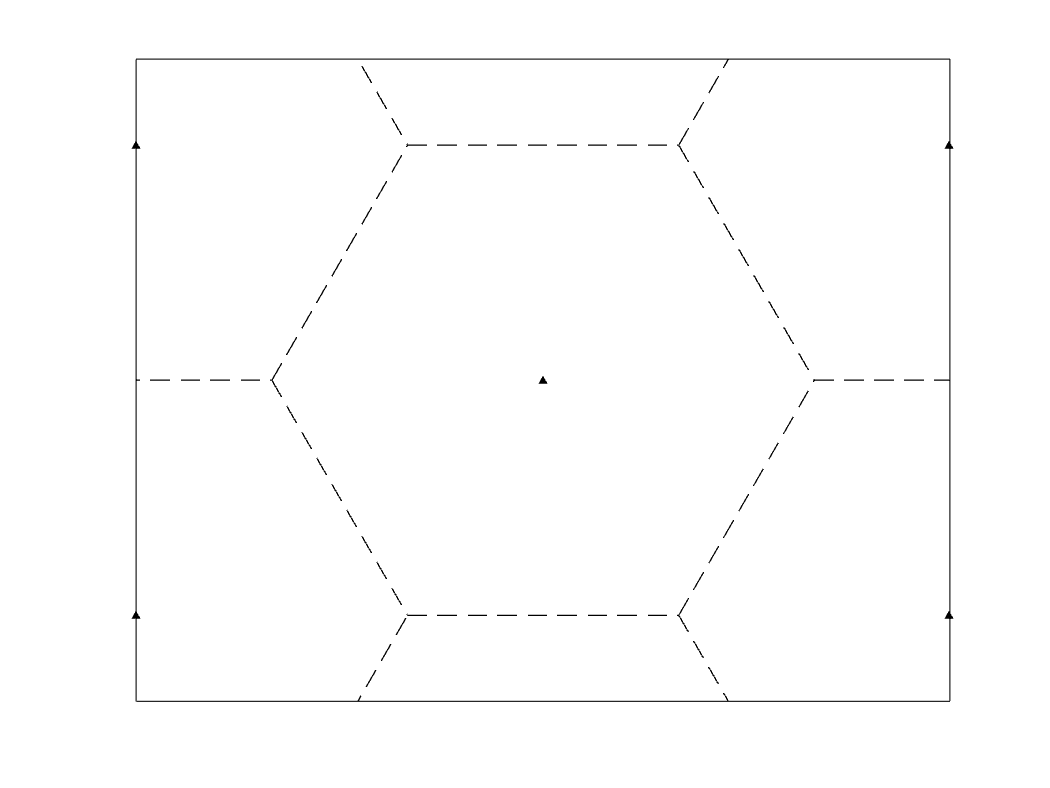

Es = zeros(num,length(kx));
for j1 = 1:length(kx)

    H = full(syst.Hamilton(kx(j1),ky));
    Es(:,j1) = eig(H);
end
figure
plot(kx,Es,'k')

syst = Kane_mele_Model(lam_so = -.24,lam_v = .7,lam_R = 0.05,Ns = 10);
syst.system_graph.Nodes

where the subscript 1 and 2 represent the spin up and down.

# Zeeman Berry Curvature

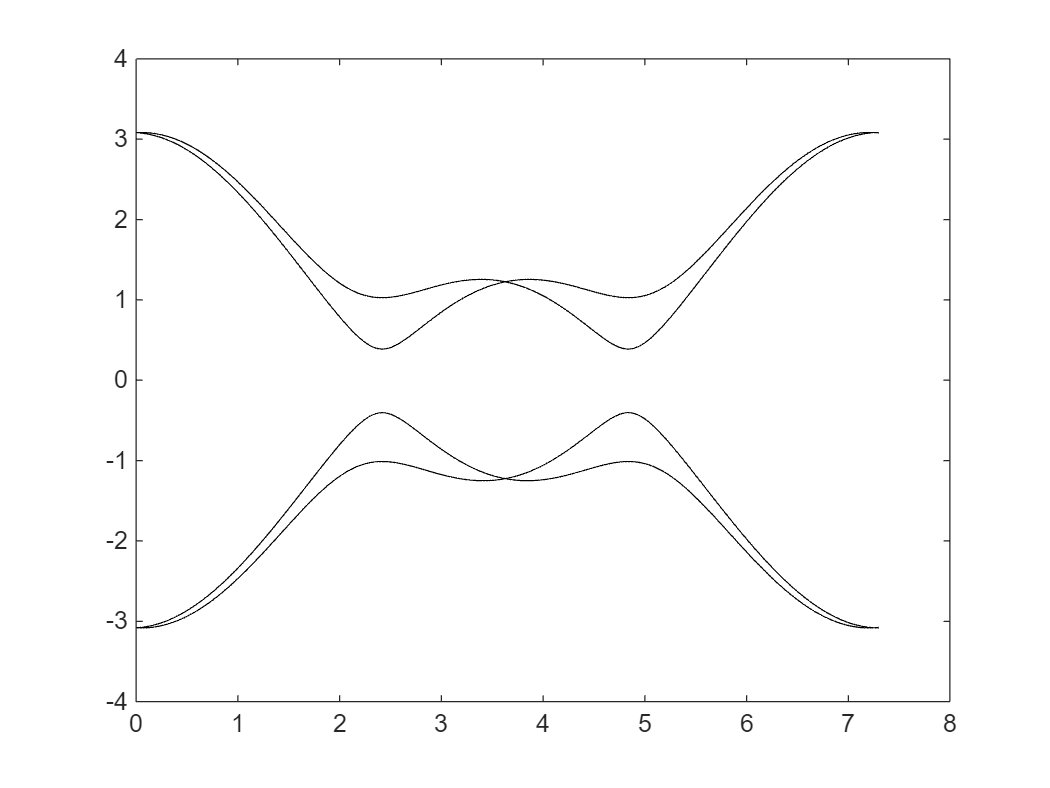

%%% Build syst
lso = -0.06; lv = 0.7; lr = 0.05;
syst = Kane_mele_Model(lam_so = lso,lam_v = lv,lam_R = lr);
% syst = Kane_mele_Model(lam_so = lso,lam_v = lv,lam_R = lr);
kx = linspace(-pi/sqrt(3),pi/sqrt(3),300*.8);
ky = linspace(0,4*pi/3,3*100);

sx = [0,1;1,0]; sy = [0,-1i;1i,0];
Sx = kron(eye(2),sx); Sy = kron(eye(2),sy);


ans = 4×1 table
         Name     
    ______________

    {'A(19,19)_1'}
    {'A(19,19)_2'}
    {'B(19,19)_1'}
    {'B(19,19)_2'}


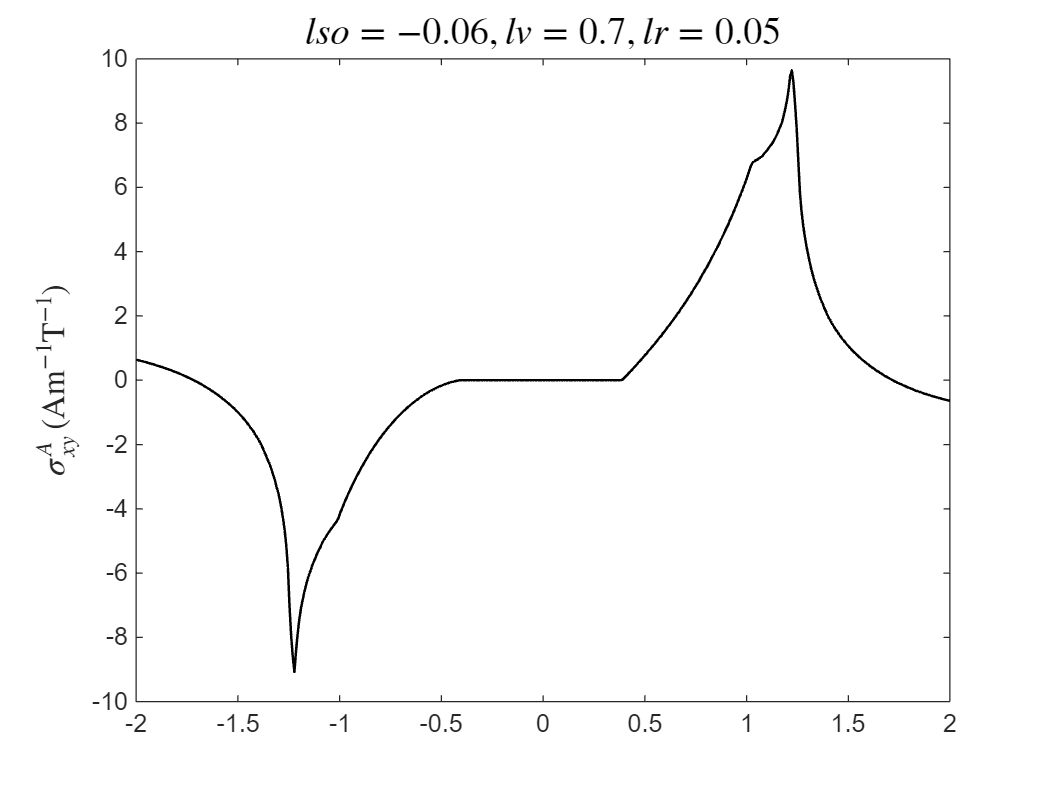

[Z_xy,Z_yx,Es] = TB_Hamilton.TopoNumber.Zeeman_curvature(syst,kx,ky,Sx,Sy,1:4);
ZA_xy = (Z_xy-Z_yx)/2;

mu = linspace(-2,2,500);
sigma = zeros(size(mu));
for j1 = 1:length(mu)
    id = Es<mu(j1);
    sigma(j1) = sum(ZA_xy(id));
end

e = 1.602*1e-19;      %(A*s)
me = 9.109*1e-31;     % kg
hbar = 1.055*1e-34;   % m^2*kg/m
mu_B = e*hbar/(2*me);
sigma1 = e*mu_B/hbar*1e10*sigma/(4*pi^2);
figure
plot(mu,sigma1,'-k','linewidth',1)
ylabel('$\sigma^A_{xy}\, \left(\mathrm{Am^{-1} T^{-1}}\right)$','Interpreter','latex','FontSize',13)
title("$lso="+num2str(lso)+", lv="+num2str(lv)+", lr="+num2str(lr)+"$",'Interpreter','latex','FontSize',15)
kx = 3*linspace(-pi/sqrt(3),pi/sqrt(3),600*.8);
ky = 3*linspace(0,4*pi/3,6*100);
sx = [0,1;1,0]; sy = [0,-1i;1i,0];
Sx = kron(eye(2),sx); Sy = kron(eye(2),sy);
%%% Calculate the distribution in pick mu=1.23
mu = 1.23;
[Z_xy,Z_yx] = TB_Hamilton.TopoNumber.Zeeman_curvature(syst,kx,ky,Sx,Sy,mu,"Energy");
ZA_xy = (Z_xy-Z_yx)/2;
[Kx,Ky] = meshgrid(kx,ky);
figure
contourf(Kx,Ky,ZA_xy',256,'EdgeColor','none')
colormap(slanCM(104,256));

yticks([])
colorbar
hold on
TB_Hamilton.Plot.FBZ(syst,0)
axis([min(kx),max(kx),min(ky),max(ky)])
clim_min = -max(abs(ZA_xy(:))); clim_max = -clim_min;
clim([clim_min,clim_max]);
colorbar('Ticks',[clim_min,0,clim_max],'FontSize',12,'FontName','Times','TickLabelInterpreter','latex');
title("$lso="+num2str(lso)+", lv="+num2str(lv)+", lr="+num2str(lr)+", E_f=" +num2str(mu)+"$",...
    'Interpreter','latex','FontSize',15)

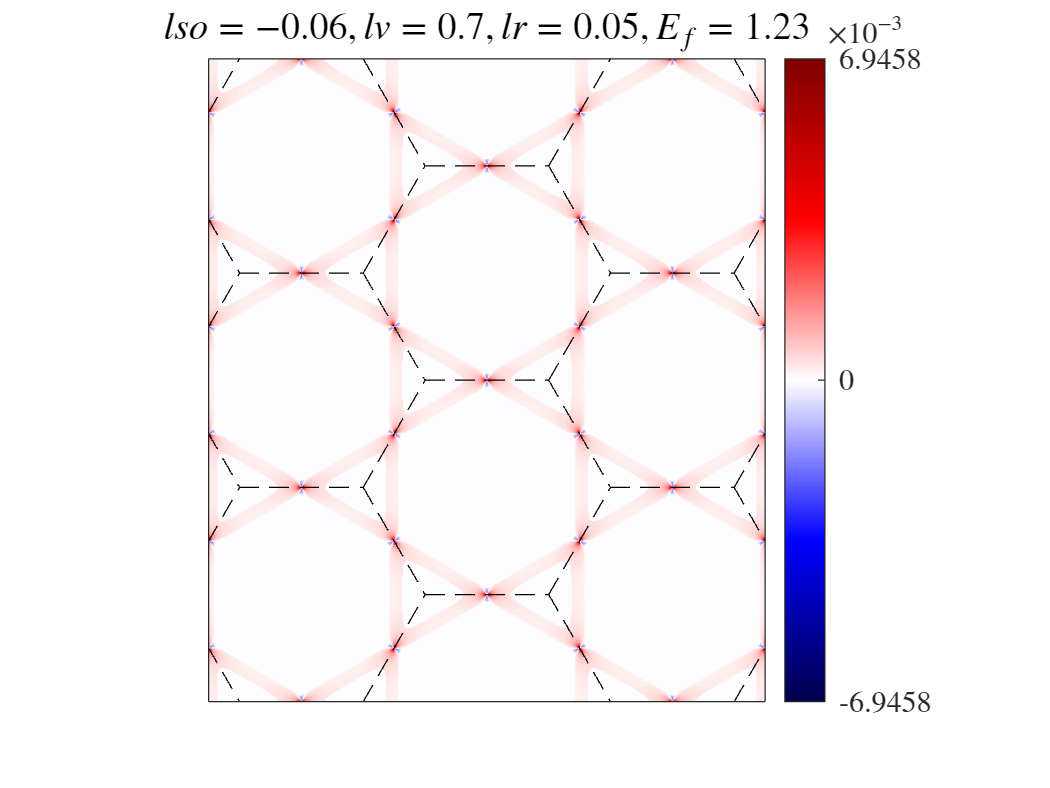

function Omega = curvature(syst,kx,ky,band)
% CURVATURE calculates the sum_m (s^a_{nm} s^b_{mn})/e_{mn} where n is
% setted by 'band'.


[s0,sx,sy,sz] = TB_Hamilton.groups.spin_matrices(1/2,0:3);
Sx = kron(s0,sx); Sy = kron(s0,sy); Sz = kron(s0,sz);
dx = kx(2)-kx(1); dy = ky(2)-ky(1);

ind = 1:4;

ind(ind==band) = [];
nx = length(kx); ny = length(ky);

ans = -0.0018

@author : slandarer


Omega = zeros(nx,ny);
parfor j1 = 1:nx
    for j2 = 1:ny
        H = syst.Hamilton(kx(j1),ky(j2));
        [V,E] = eig(full(H));
        Omega_ = 0;
        for i1 = ind
            Delta = E(band,band)-E(i1,i1);
            Omega_ = Omega_ + (V(:,band)'*Sz*V(:,i1)*V(:,i1)'*Sy*V(:,band))/Delta; % To modify Sz-> Sy calculate the SySy.
        end
        Omega(j1,j2) = Omega_*dx*dy;
    end
end
end

kx = 2*linspace(-pi/sqrt(3),pi/sqrt(3),800*.8);
ky = 2*linspace(0,4*pi/3,8*100);
syst = Kane_mele_Model(lam_so = .06,lam_v = .1,lam_R = 0.05,Ns = 1);
Omega1 = curvature(syst,kx,ky,1);
Omega2 = curvature(syst,kx,ky,2);

Omega1r_ = medfilt1(real(Omega1'),'omitnan');
Omega2r_ = medfilt1(real(Omega2'),'omitnan');
Omega1i_ = medfilt1(imag(Omega1'),'omitnan');
Omega2i_ = medfilt1(imag(Omega2'),'omitnan');

disp(['The real part: ',num2str(sum(Omega1r_+Omega2r_,'all')/(4*pi^2))])
disp(['The imag part: ',num2str(sum(Omega1i_+Omega2i_,'all')/(4*pi^2))])

figure
[Kx,Ky] = meshgrid(kx,ky);
contourf(Kx,Ky,(Omega1_+Omega2_),256,'EdgeColor','none')
colormap(slanCM(104,256));
yticks([])
colorbar
hold on
TB_Hamilton.Plot.FBZ(syst)

% axis equal;
axis([min(kx),max(kx),min(ky),max(ky)])
clim_min = -max(abs(Omega1_(:))); clim_max = max(abs(Omega1_(:)));
clim([clim_min,clim_max]/2);
colorbar('Ticks',[clim_min,0,clim_max],'FontSize',12,'FontName','Times','TickLabelInterpreter','latex');

The real part: 1.1998e-19


The imag part: 2.3173e-15
